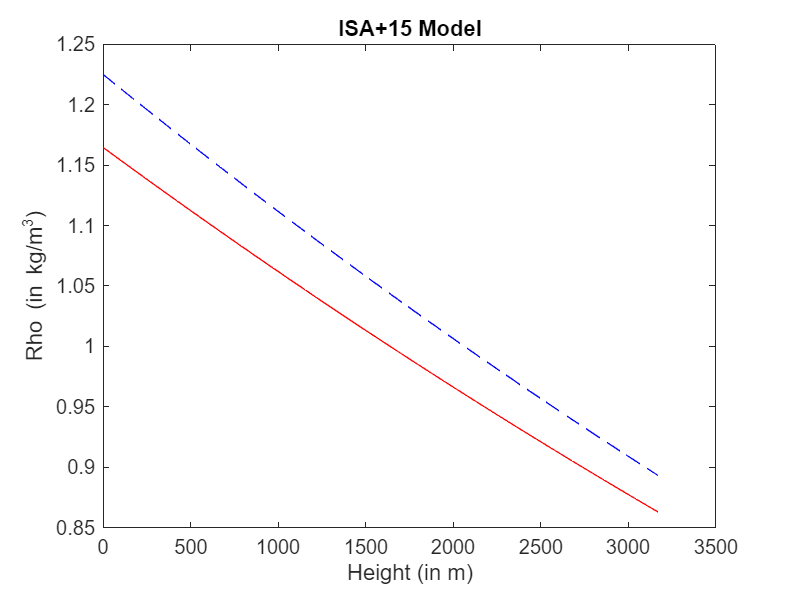

a = 0.0065;
g = 9.80665;
T0 = 303.15;
R = 287;
P0 = 101325;

rho = (P0/(R*T0))*power(1-((a*Hm)/T0),(g/(a*R))-1);
plot(Hm,rho,'r-',Hm,kgm3,'b--');

xlabel("Height (in m)");
ylabel("Rho (in kg/m^3)");
title("ISA+15 Model");

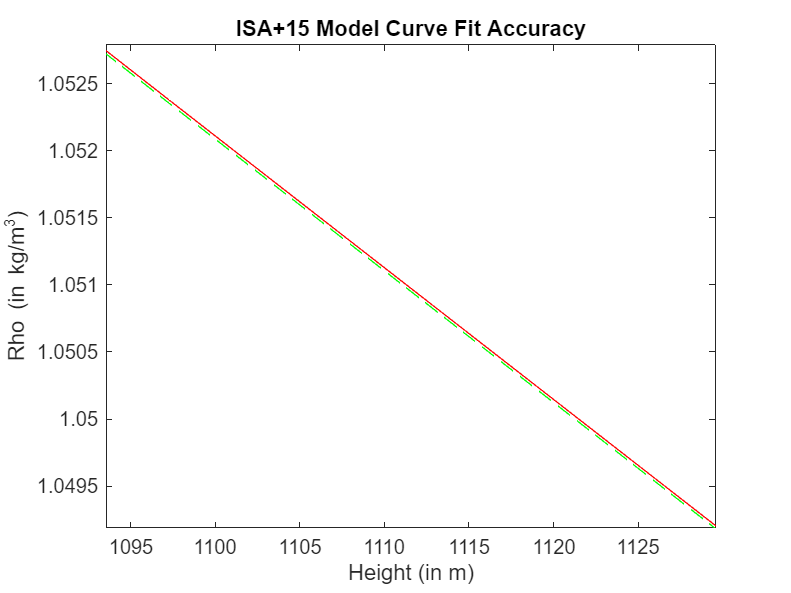

p1 = 3.4338e-09;
p2 = -1.0595e-04;
p3 = 1.1645;
func = p1*Hm.^2 + p2*Hm + p3;

plot(Hm,func,'r-',Hm,rho,'g--');

xlabel("Height (in m)");
ylabel("Rho (in kg/m^3)");
title("ISA+15 Model Curve Fit Accuracy");

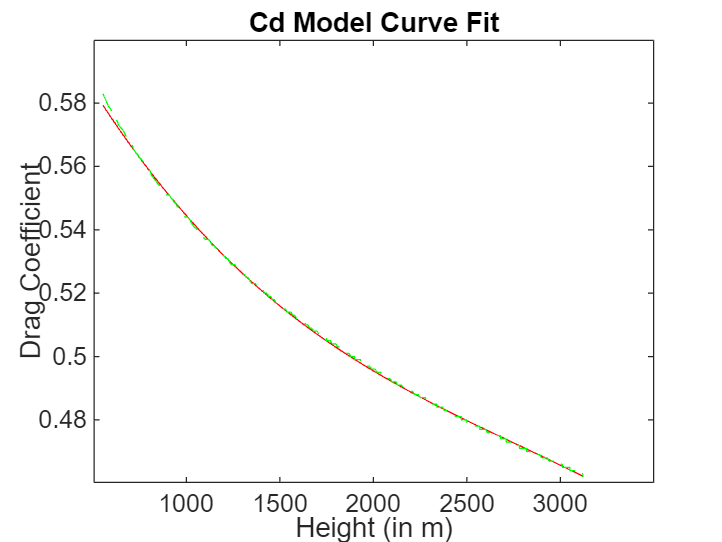

format long

a = -4.278e-12;
b = 3.53e-08;
c = -0.000125;
d = 0.6385;

cdf = a*power(alt_m,3) + b*power(alt_m,2) + c*alt_m + d;
plot(alt_m,cdf,'r-',alt_m,dragcoeff,'g--');

xlabel("Height (in m)");
ylabel("Drag Coefficient");
title("Cd Model Curve Fit");


syms s x y z
f(s) = x.*(s.^3) + y.*(s.^2) + z.*s; 
g = finverse(f,s)

$$g(s) = \begin{array}{l} \frac{\frac{y^{2}}{9\,x^{2}}-\frac{z}{3\,x}}{\sigma_{1}}-\frac{y}{3\,x}+\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}={\left(\sqrt{{\left(\frac{s}{2\,x}-\frac{y^{3}}{27\,x^{3}}+\frac{y\,z}{6\,x^{2}}\right)}^{2}-{\left(\frac{y^{2}}{9\,x^{2}}-\frac{z}{3\,x}\right)}^{3}}-\frac{y^{3}}{27\,x^{3}}+\frac{s}{2\,x}+\frac{y\,z}{6\,x^{2}}\right)}^{1/3} \end{array}$$